clear variables;

R=3;C=1/9;L=9/2;
A=[-1/R/C -1/C;1/L 0];
eig(A)% the eigen values

ans =     -2
    -1


syms s
tm=ilaplace(inv(s*eye(2)-A))% symbolic transition matrix

$$tm = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-2\,t}-{\mathrm{e}}^{-t} & 9\,{\mathrm{e}}^{-2\,t}-9\,{\mathrm{e}}^{-t}\\ \frac{2\,{\mathrm{e}}^{-t}}{9}-\frac{2\,{\mathrm{e}}^{-2\,t}}{9} & 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} \end{array}\right)$$

collect(simplify(tm),'t')

$$ans = \left(\begin{array}{cc} -{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-2\right) & -9\,{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-1\right)\\ \frac{2\,{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-1\right)}{9} & 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} \end{array}\right)$$

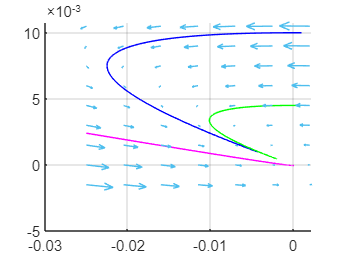

%%
t=linspace(0,1/2*6,1e3);
tm11=-exp(-2*t).*(exp(t) - 2);tm12=-9*exp(-2*t).*(exp(t) -1);
tm21=(2*exp(-2*t).*(exp(t) - 1))/9;tm22=2*exp(-t) - exp(-2*t);

hold on;
x01=0.001;x02= 0.01;% initial conditions
x1=tm11*x01+tm12*x02;
x2=tm21*x01+tm22*x02;
plot(x1,x2,'b');
[x1,x2] = meshgrid((-0.025:0.0045:0.0025),(-0.0015:0.0015:0.011));
x1d=A(1,1)*x1+A(1,2)*x2;
x2d=A(2,1)*x1+A(2,2)*x2;
quiver(x1,x2,x1d,x2d);grid;shg;


%%
x011=0.001;x022= 0.0045;% initial conditions
x11=tm11*x011+tm12*x022;
x22=tm21*x011+tm22*x022;
plot(x11,x22,'g');
[x11,x22] = meshgrid((-0.025:0.0045:0.0025),(-0.0015:0.0015:0.011));
x11d=A(1,1)*x11+A(1,2)*x22;
x22d=A(2,1)*x11+A(2,2)*x22;
quiver(x11,x22,x11d,x22d);grid;shg;

%%
x0111=-0.025;x0222= 0.0024;% initial conditions
x111=tm11*x0111+tm12*x0222;
x222=tm21*x0111+tm22*x0222;
plot(x111,x222,'m');
[x111,x222] = meshgrid((-0.025:0.0045:0.0025),(-0.0015:0.0015:0.011));
x111d=A(1,1)*x111+A(1,2)*x222;
x222d=A(2,1)*x111+A(2,2)*x222;
quiver(x111,x222,x111d,x222d);grid;shg;
hold off;